data = [
9.83,	12.3,	3.13,	7.83;
12.31,	14.2,	5.61,	11.12;
6.18,	9.72,	10.31,	9.31;
7.69,	14.3,	7.4,	13.4;
13.11,	8.81,	7.31,	17.3;
8.91,	7.61,	9.1,	14.18;]

data =     9.8300   12.3000    3.1300    7.8300
   12.3100   14.2000    5.6100   11.1200
    6.1800    9.7200   10.3100    9.3100
    7.6900   14.3000    7.4000   13.4000
   13.1100    8.8100    7.3100   17.3000
    8.9100    7.6100    9.1000   14.1800


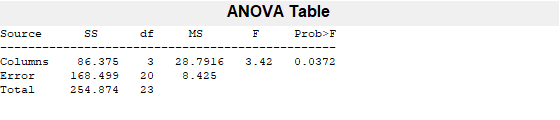

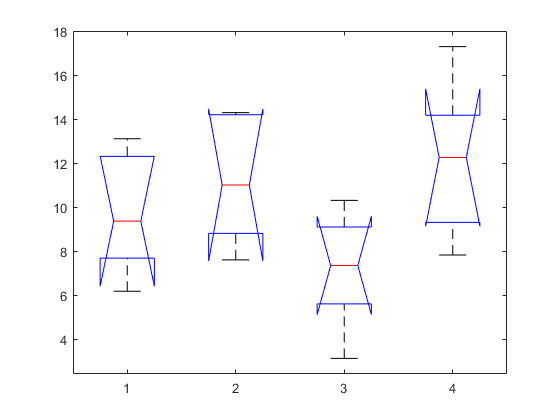

p = 0.0372

tbl = 4×6 cell array
    {'Source' }    {'SS'      }    {'df'}    {'MS'      }    {'F'       }    {'Prob>F'  }
    {'Columns'}    {[ 86.3747]}    {[ 3]}    {[ 28.7916]}    {[  3.4174]}    {[  0.0372]}
    {'Error'  }    {[168.4994]}    {[20]}    {[  8.4250]}    {0×0 double}    {0×0 double}
    {'Total'  }    {[254.8741]}    {[23]}    {0×0 double}    {0×0 double}    {0×0 double}


stat = struct with fields:
    gnames: [4×1 char]
         n: [6 6 6 6]
    source: 'anova1'
     means: [9.6717 11.1567 7.1433 12.1900]
        df: 20
         s: 2.9026


[p,tbl,stat] = anova1(data)

disp(p)

    0.0372



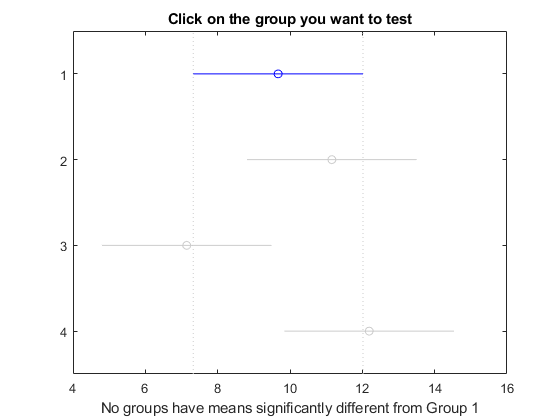

ans =     1.0000    2.0000   -6.1755   -1.4850    3.2055    0.8120
    1.0000    3.0000   -2.1621    2.5283    7.2188    0.4511
    1.0000    4.0000   -7.2088   -2.5183    2.1721    0.4544
    2.0000    3.0000   -0.6771    4.0133    8.7038    0.1105
    2.0000    4.0000   -5.7238   -1.0333    3.6571    0.9256
    3.0000    4.0000   -9.7371   -5.0467   -0.3562    0.0321


multcompare(stat, 'cType', 'hsd')